# RVC2: Chapter 15 - Visual Servoing

format compact
close all
clear
clc

## 15.1  Position-based visual servoing

cam = CentralCamera('default');

principal point not specified, setting it to centre of image plane


creating new figure for camera


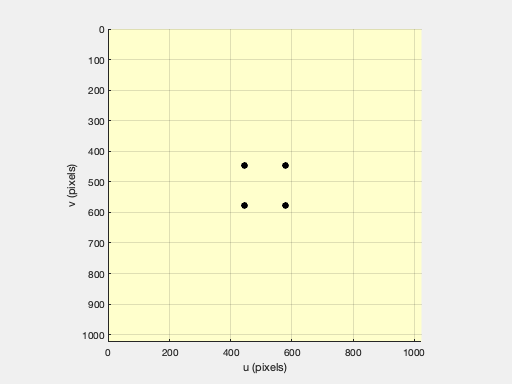

h =   Axes with properties:

             XLim: [0 1024]
             YLim: [0 1024]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


p =   445.3333  445.3333  578.6667  578.6667
  445.3333  578.6667  578.6667  445.3333



P = mkgrid( 2, 0.5, 'pose', SE3(0,0,3) );

T_C = SE3(0,0,0);  %DIFF
Cd_T_G = SE3(0.1, 0.2, 0.5); %DIFF
p = cam.plot(P, 'pose', T_C)


C_Te_G = cam.estpose(P, p);

T_delta = C_Te_G * inv(Cd_T_G);

lambda = 0.2;  %DIFF
T_C = T_C .* T_delta.interp(SE3, lambda);

T_C0 = SE3(1,1,-3)*SE3.Rz(0.6);

Cd_T_G = SE3(0, 0, 1);

pbvs = PBVS(cam, 'pose0', T_C0, 'posef', Cd_T_G, 'axis', [-1 2 -1 2 -3 0.5])

 
pbvs = 
Visual servo object: camera=default
  200 iterations, 0 history
  P= -0.25       -0.25        0.25        0.25                 
     -0.25        0.25        0.25       -0.25                 
         0           0           0           0                 
  C_T0:   t = ( 1,  1,  -3), R = ( 34.3775deg |  0,  0,  1)    
  C*_T_G: t = ( 0,  0,  1), R = nil                            


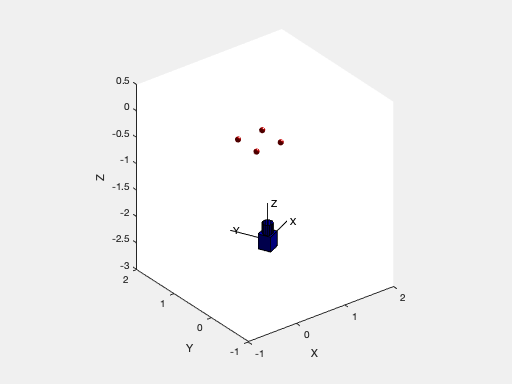

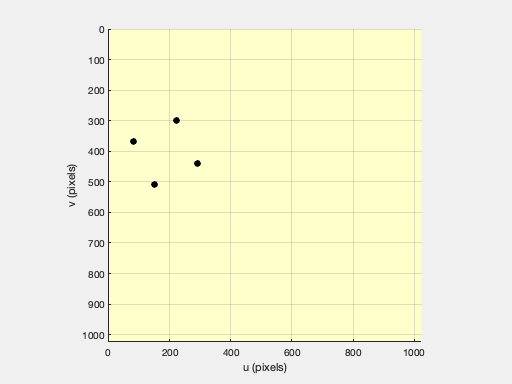

completed on iteration count



pbvs.run(5);


pbvs.plot_p();

Can only plot image plane trajectories for point-based IBVS


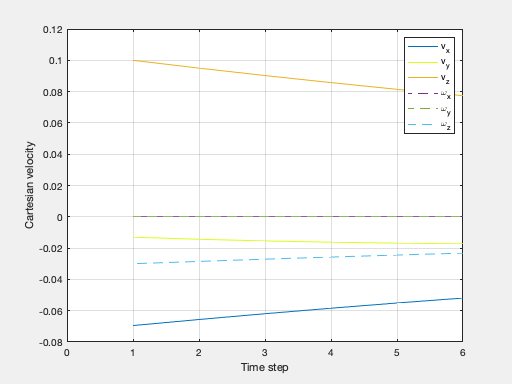

pbvs.plot_vel();

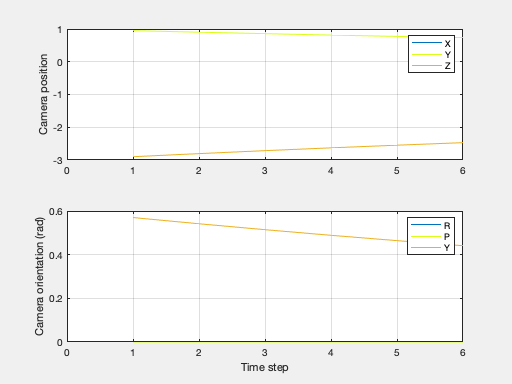

pbvs.plot_camera();

## 15.2  Image-based visual servoing

## 15.2.1  Camera and image motion

cam = CentralCamera('default');

P = [1 1 5]';

p0 = cam.project( P )

px = cam.project( P, 'pose', SE3(0.1,0,0) )

( px - p0 ) / 0.1

( cam.project( P, 'pose', transl(0, 0, 0.1) ) - p0 ) / 0.1

( cam.project( P, 'pose', trotx(0.1) ) - p0 ) / 0.1

J = cam.visjac_p([672; 672], 5)


clf
cam.flowfield( [1 0 0 0 0 0] );

cam.flowfield( [0 0 1 0 0 0] );

cam.flowfield( [0 0 0 0 0 1] );

cam.flowfield( [0 0 0 0 1 0] );

cam.visjac_p(cam.pp', 1)

cam.f = 20e-3;
cam.flowfield( [0 0 0 0 1 0] );

cam.f = 4e-3;
cam.flowfield( [0 0 0 0 1 0] );

J = cam.visjac_p(cam.pp', 1);
null(J)

## 15.2.2  Controlling feature motion

cam = CentralCamera('default');

P = mkgrid( 2, 0.5, 'pose', SE3(0,0,3) );

pd = bsxfun(@plus, 200*[-1 -1 1 1; -1 1 1 -1], cam.pp');

T_C = SE3(0,0,0); %DIFF
%transl(1,1,-3)*trotz(0.6)

p = cam.plot(P, 'pose', T_C)

e = pd - p;

J = cam.visjac_p(p, 1);

v = lambda * pinv(J) * e(:);

T_C = T_C .* SE3.delta(v);

T_C0 = SE3(1,1,-3)*SE3.Rx(0.6)

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd)

ibvs.run();

ibvs.plot_p();
ibvs.plot_vel();
ibvs.plot_camera();


sl_ibvs

r = sim('sl_ibvs')

t = r.find('tout');
v = r.find('yout').signals(2).values;
about(v)

plot(t, v)

p = r.find('yout').signals(1).values;
about(p)
plot2(p)

## 15.2.3  Estimating feature depth

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depth', 1)
ibvs.run(50)


ibvs.plot_p(); % DIFF
ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depth', 10)
ibvs.run(50)
ibvs.plot_p(); % DIFF

ibvs = IBVS(cam, 'pose0', T_C0, 'pstar', pd, 'depthest')
ibvs.run()
ibvs.plot_z()
ibvs.plot_p()

## 15.2.4  Performance issues

pbvs.T0 = SE3(-2.1, 0, -3)*SE3.Rz(5*pi/4);
pbvs.run()
ibvs.plot_p();

ibvs = IBVS(cam, 'pose0', pbvs.T0, 'pstar', pd, 'lambda', 0.002, 'niter', Inf, 'eterm', 0.5)
ibvs.run()
ibvs.plot_p();

ibvs = IBVS(cam, 'pose0', SE3(0,0, -1)*SE3.Rz(1), 'pstar', pd);
ibvs.run()
ibvs.plot_camera

ibvs = IBVS(cam, 'pose0',  transl(0,0, -1)*trotz(pi), ...
    'pstar', pd, 'niter', 10);
ibvs.run()
ibvs.plot_camera

## 15.3  Using other image featueres

## 15.3.1  Line features

P = circle([0 0 3], 0.5, 'n', 3);

ibvs = IBVS_l(cam, 'example');
ibvs.run()

## 15.3.2  Circle features

P = circle([0 0 3], 0.5, 'n', 10);

Tc = SE3; %DIFF
p = cam.project(P, 'pose', Tc);

pn = cam.normalized(p)
x = pn(1,:); y = pn(2,:);
a = [y.^2; -2*x.*y; 2*x; 2*y; ones(1,numcols(x))]';
b = -(x.^2)';
E = a\b;

plane = [0 0 1 -3]; %DIFF
J = cam.visjac_e(E, plane)

ibvs = IBVS_e(cam, 'example');
clf % DIFF
ibvs.run()


bdclose('all')